# **Numerical Integration (Simpson's 1/3)**

Function

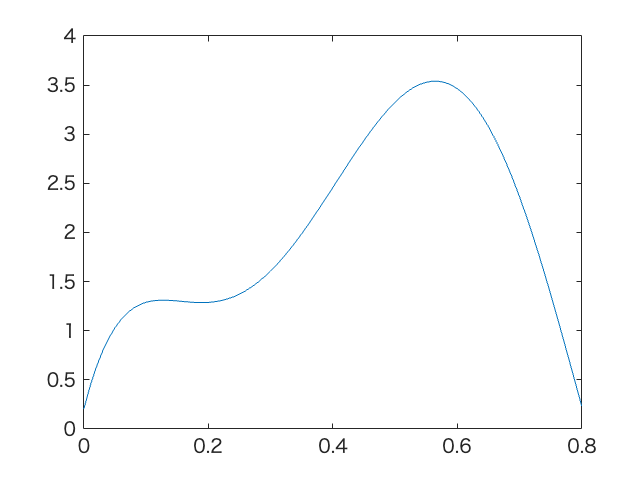

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = 0 : 0.01 : 0.8;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from 0 to 0.8

format long
a = 0;
b = 0.8;
p = [400 -900 675 -200 25 0.2];
q = polyint(p) % integrate polynomial equation (gives us the EXACT integration)

q = 1.0e+02 *

   0.666666666666667  -1.800000000000000   1.687500000000000  -0.666666666666667   0.125000000000000   0.002000000000000                   0


Itrue = diff(polyval(q, [a, b])) % for relative value

Itrue =    1.640533333333333


Plot original function along with simpson 1/3 rule with ns = 1

ns = 1

ns =      1


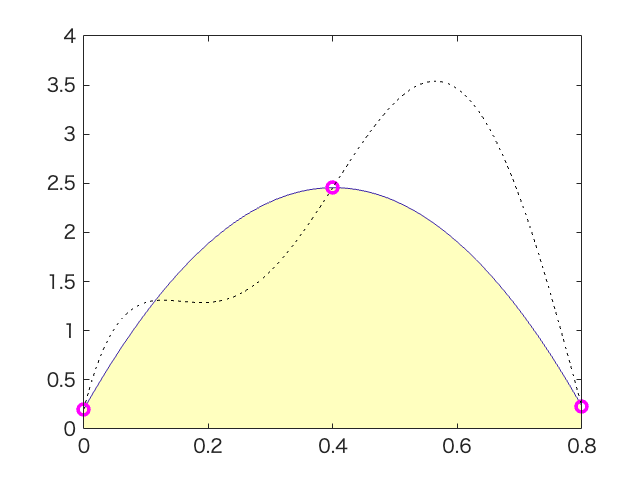

x = linspace(0, 0.8, 2*ns+1);
y = f(x);

p2 = polyfit(x, y, 2);
yy2 = polyval(p2, xx);

figure
area(xx, yy2, 'FaceColor','y','FaceAlpha',0.25,'EdgeColor','flat','LineStyle','-')
hold on
plot(x, y, 'mo', 'LineWidth', 2)
hold on
plot(xx, yy, 'k:')

Plot original function along with simpson 1/3 rule from n = 1 to 10

ns = 10

ns =     10


k =      1


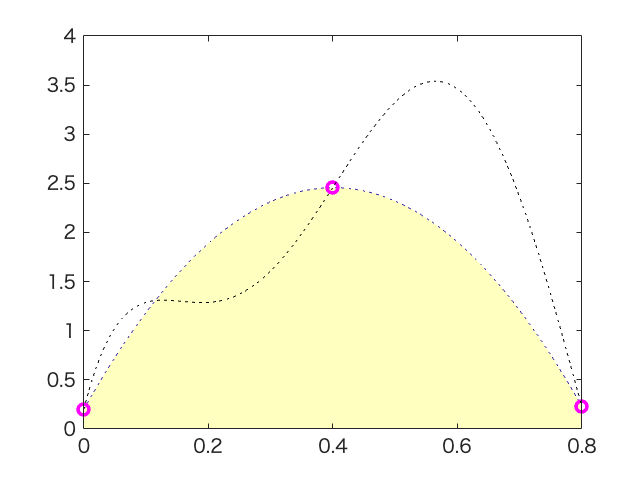

k =      2


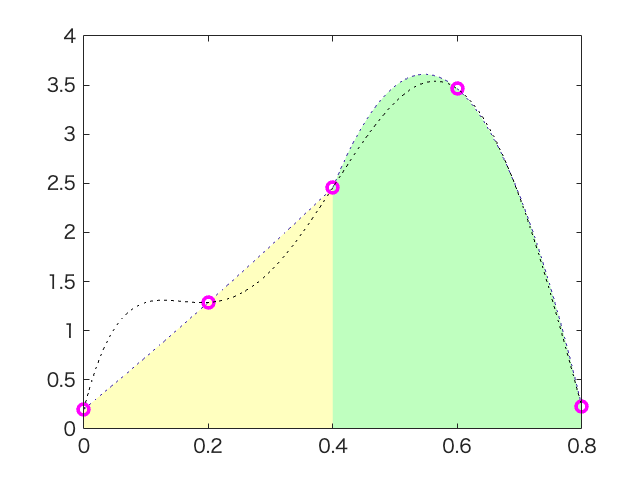

k =      3


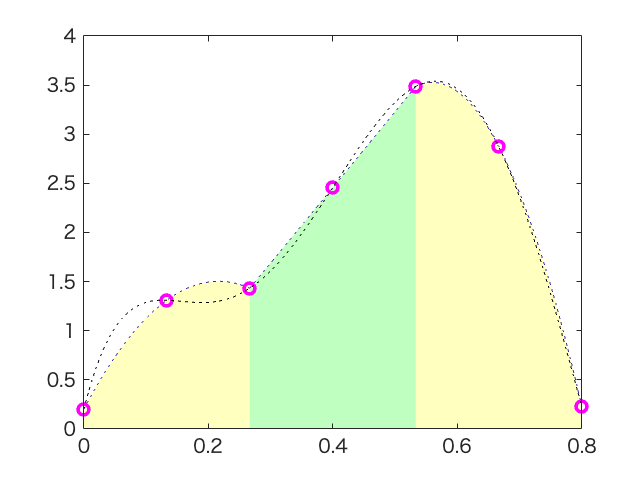

k =      4


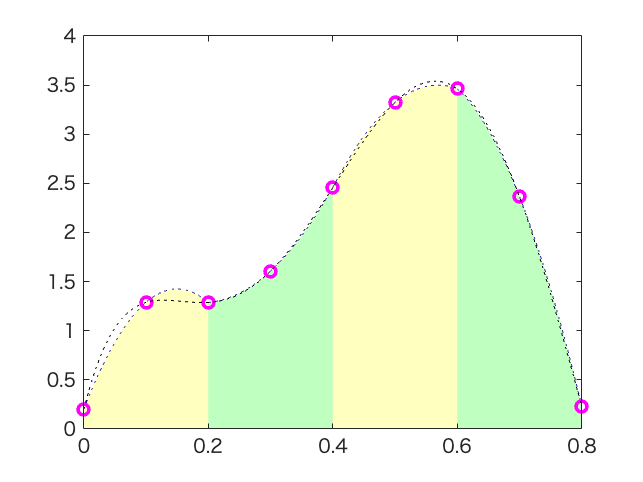

k =      5


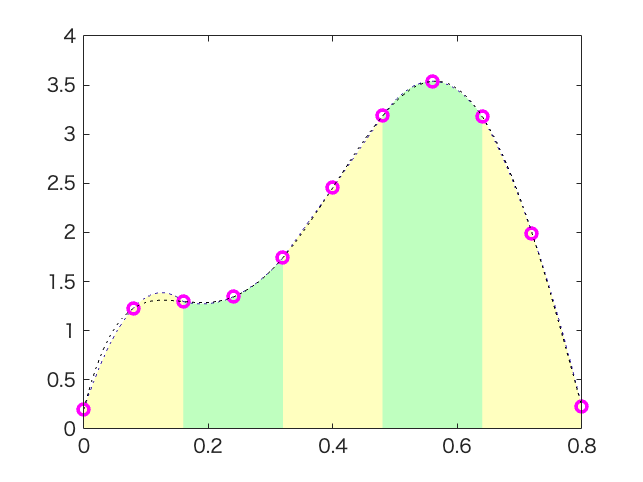

k =      6


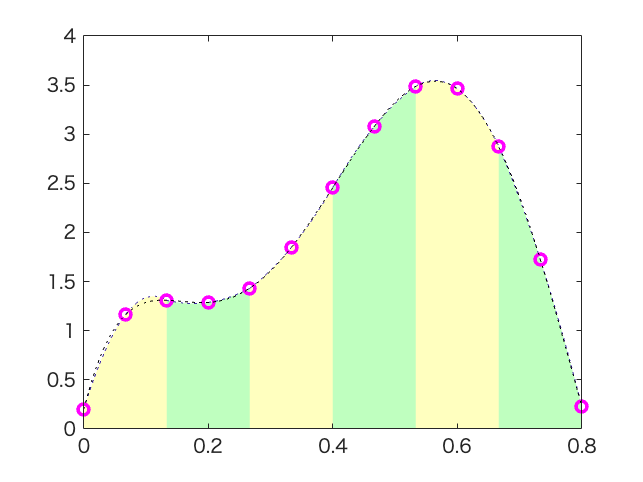

k =      7


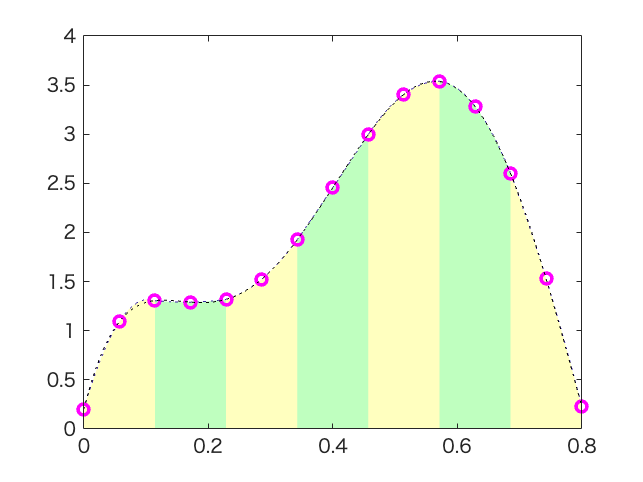

k =      8


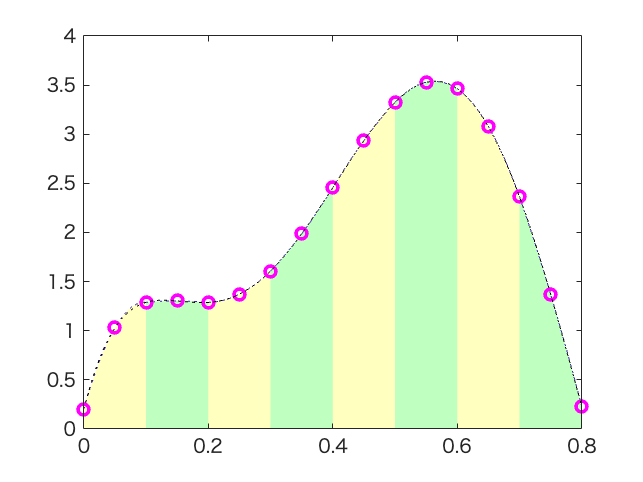

k =      9


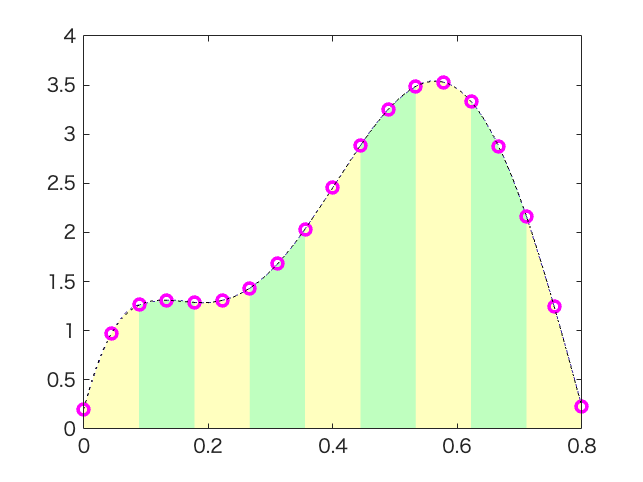

k =     10


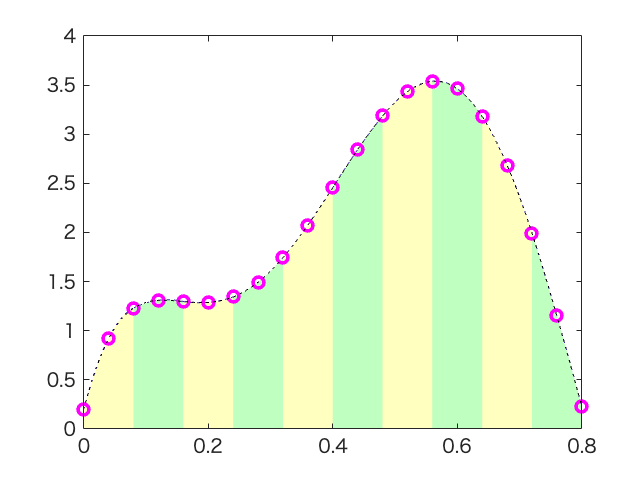

for k = 1:ns
    k
    x = linspace(0, 0.8, 2*k+1);
    y = f(x);
    figure
    colors = ['g','y'];
    for i = 1:k
        ileft = 2*(i-1)+1;
        iright = 2*i+1;
        newx = x(ileft:iright);
        newy = y(ileft:iright);
        p2 = polyfit(newx, newy, 2);
        xx2 = linspace(x(ileft), x(iright));
        yy2 = polyval(p2, xx2);
        area(xx2, yy2, 'FaceColor',colors(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
        hold on
        plot(newx, newy, 'mo', 'LineWidth', 2)
        hold on
    end
    plot(xx, yy, 'k:')
    %hold off
end